# **Esercitzione n*4 - Identificazione di modelli compartimentali lineari**

## **Descrizione del problema**

Si identifichi il modello compartimentale del C-peptide analizzato nell’esercitazione 1 sulla base dei dati ottenuti dall’esperimento descritto nell’esercitazione 3, usando la tecnica dei minimi quadrati o dei minimi quadrati pesati (segliere quella opportuna sulla base del modello dell’errore). Dopo aver ricavato analiticamente le relazioni che intercorrono tra i parametri del modello compartimentale e quelli del modello esponenziale adottato nell’esercitazione 3, si confrontino tra di loro le stime ottenute nelle due esercitazioni. Sono uguali? Sono simili? Con quale delle due parametrizzazioni ottengo CV piu' bassi?Si utilizzi la tecnica piu' appropriata tra Monte Carlo e/o bootstrap per la valutazione dell’affidabilita' delle stime e si confrontino i risultati con quelli ottenuti con la tecnica dei minimi quadrati.

clearvars; 
close all;
clc;

## **Identificazione di modelli**

Il processo di identificazione consente di stimare modelli di sistemi a partire da dati sperimentali. Affinche' un modello risulti completamente determinato e' necessario stabilire sia la sua struttura, sia il valore numerico dei parametri. Questi ultimi sono solitamente stimati a partire da esperimenti che consistono nella stimolazione del sistema fisico con un determinato numero di ingressi e nella misurazione di altrettante uscite in un insieme finito di istanti di tempo. 

## Identificazione del modello compartimentale del C-peptide

Per stabilire la relazione che intercorre tra i parametri, e' necessario derivare l'andamento della concentrazione nel compartimento accessibile. Una volta creato il sistema LTI, ne calcolo la funzione di traferimento, i fratti semplici e si prosegue con l'antitrasformata. 

Il modello e' il seguente:

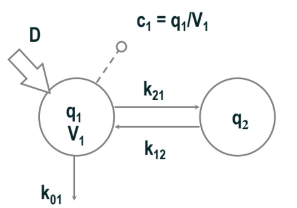   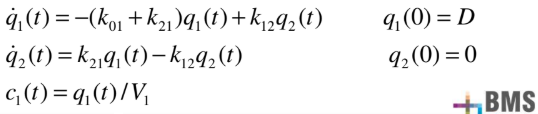

Creazione del sistema LTI.

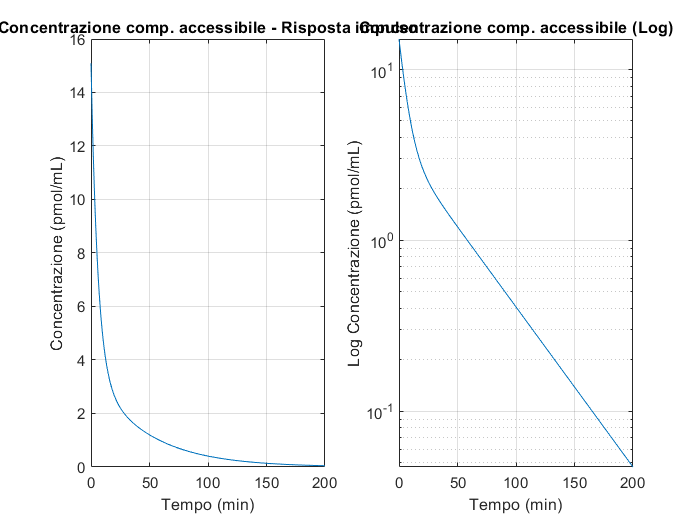

% Dati modello 
k01 = 6.54e-2;
k12 = 5.68e-2;
k21 = 7.16e-2;
V1 = 3290;
d = 49650;

% Matrici del sistema compartimentale lineare
A = [-(k01+k21),k12;k21,-k12]; 
B = [d;0];
C = [1/V1,0];
D = 0;

% Creazione del modello compartimentale lineare
sys = ss(A,B,C,D);

% Impulso 
t = [0:1:200];
[c,T] = impulse(sys,t);

figure(1);
plot(T,c), xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazione comp. accessibile - Risposta impulso");
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(T,c), xlabel("Tempo (min)"), ylabel("Log Concentrazione (pmol/mL)"), grid on, 
title("Concentrazione comp. accessibile (Log)");

Calcolo della funzione di trasferimento per poter usare i fratti semplici.

% Calcolo della funzione di trasferimento 
tf(sys)


ans =
 
      15.09 s + 0.8572
  -------------------------
  s^2 + 0.1938 s + 0.003715
 
Continuous-time transfer function.



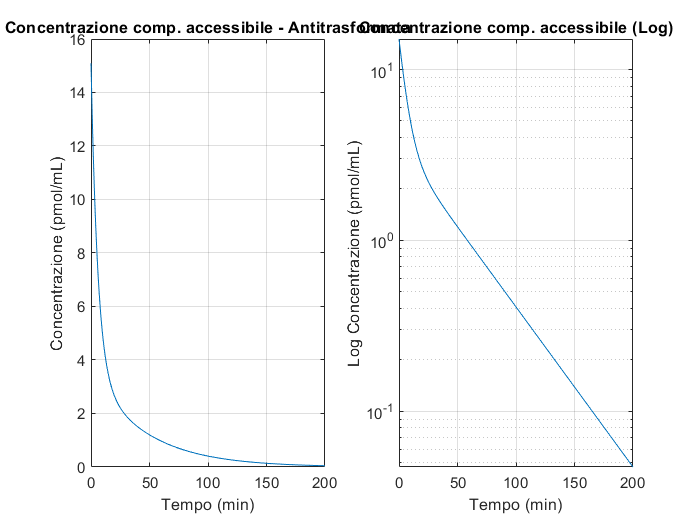


% Calcolo numeratore e denomitore della funzione di trasferimento 
[num,den] = tfdata(sys,"v");

% Calcolo zeri e poli della funzione di trasferimento
[zero,pole,gain] = zpkdata(sys,"v");
p1 = pole(1);
p2 = pole(2);

% Applico i fratti semplici
res = residue(num,den);
r1 = res(1);
r2 = res(2);

% Antitrasformata
c_a = r1*exp(p1*T)+r2*exp(p2*T);

figure(2);
plot(T,c_a), xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazione comp. accessibile - Antitrasformata"), 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(T,c_a), xlabel("Tempo (min)"), ylabel("Log Concentrazione (pmol/mL)"), grid on, 
title("Concentrazione comp. accessibile (Log)"); 

Per verficare che i parametri ricavati con l'anti trasformata siano corretti, effettuo un confronto tra le curve di concentrazione ottenute con i diversi metodi. 

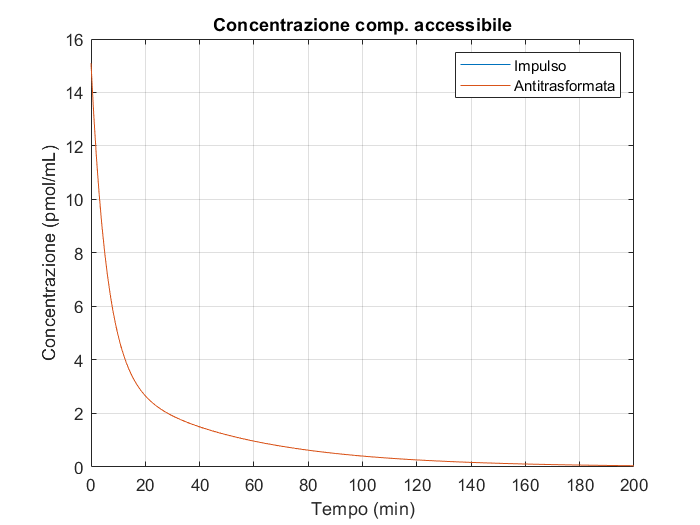

figure(3);
plot(T,c,T,c_a), xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazione comp. accessibile"), legend("Impulso","Antitrasformata");

**Commento:** il fatto che le due curve si sovrappongano perfettamente indica che il metodo dell'antitrasformata e' stato applicato in modo corretto. 

I parametri ricavati sono i seguenti: 

disp(["A = ",num2str(r1),"alfa = ",num2str(-p1),"B = ",num2str(r2),"beta = ",num2str(-p2)]);

    "A = "    "11.5622"    "alfa = "    "0.17223"    "B = "    "3.529"    "beta = "    "0.021568"

